# Second order models and under-damped responses 

The purpose of this file is to allow students to explore 2nd order behaviours and the impact of changing damping ratio and natural frequency on those behaviours. Specifically, plots are generated which overlay behaviours for a range of choices.

For convenience, as the focus is with 2nd order systems behaviour and under-damping, this script assumes zero initial conditions and will use Laplace methods as they are somewhat easier to code. We also assume a constant input of unity and a steady-state gain of unity as the focus is on model dynamics rather than dynamics coming from the input.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

BELOW is SECTION 2


File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Preliminaries

- Impact of changing damping with a constant natural frequency

- Impact of changing natural frequency

## **1. Preliminaries**

Let the ODE model and Laplace equivalent be given as:

$a_2 \frac{d^2 x}{dt^2 }+a_1 \frac{\textrm{dx}}{\textrm{dt}}+a_{o\;} x=1$    or    $X\left(s\right)=\frac{1}{a_2 s^2 +a_1 s+a_0 }\times \frac{1}{s}$

The characteristic under-damped or normalised form is given as:

$a_2 s^2 +a_1 s+a_0 =a_2 \left(s^2 +2\zeta \omega_n s+\omega_n^2 \right)$ where $\zeta \;$is the damping ratio, assumed between 0 and 1 for an under-damped system and $\omega_n$ is the natural frequency.

We wish to explore the behaviour of the system as these two parameters change, so explore the behaviour of a model step response:


$$X\left(s\right)=\frac{1}{s^2 +2\zeta \omega_n s+\omega_n^2 }\times \frac{\omega_n^2 }{s}$$
     

 **Note**, for convenience/normalisation only, we have take the steady-state gain $\frac{1}{a_{o\;} }$to be unity.

The responses below validate the following observations:

- As damping gets smaller, overshoot/undershoot are larger and it takes more periods for these to decay (decay per oscillation is slower).

- The time scale is inversely proportional to the natural frequency so larger wn means faster convergence/oscillation, for the same damping.

## 2. Impact of changing damping with a constant natural frequency

This section will demonstrate that changing the natural frequency, does not impact on the associated insights. Take a fixed natural frequency and explore how the response varies with damping. The two figures below show that, apart from the time scale, the response variation with damping is invariant under changes in natural frequency.

You can investigate different systems by changing *wn* and other values in the code below.

disp('BELOW is SECTION 2')

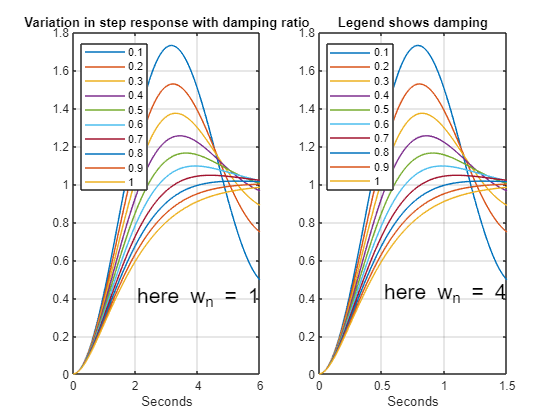

G=cell(1,10); y = cell(1,10);leg=cell(1,10);

wn=1;   
t = linspace(0,6/wn,100);
damping =[0.1:.1:1];
figure;clf;
subplot(121)
for k=1:10
    G{k}=tf(wn^2,[1,2*wn*damping(k),wn^2]);
    [y{k}]=step(G{k},t);
    plot(t,y{k});hold on
    leg{k}=num2str(damping(k));
end
grid
title(['Variation in step response with damping ratio'])
text(2/wn,0.4,['here w_n = ',num2str(wn)],'fontsize',16)
xlabel('Seconds')
legend(leg,'Location',"northwest")

%%% Example 2 - faster natural frequency
wn=4;   
t = linspace(0,6/wn,100);
damping =[0.1:.1:1];
subplot(122)
for k=1:10 
    G{k}=tf(wn^2,[1,2*wn*damping(k),wn^2]);
    [y{k}]=step(G{k},t);
    plot(t,y{k});hold on
    leg{k}=num2str(damping(k));
end
grid
title(['Legend shows damping ratio'])
text(2/wn,0.42,['here w_n = ',num2str(wn)],'fontsize',16)
legend(leg,'Location',"northwest")
xlabel('Seconds')

## 3. Impact of changing natural frequency

This section will demonstrate that changing the natural frequency changes the oscillation frequency and time scales, for a fixed damping, but the overshoot/undershoot values remain constant if the damping is constant. 

You can investigate different systems by changing damping and other values in the code below.

disp('BELOW is SECTION 2')
disp(' ');

BELOW is SECTION 2


G1=cell(1,10); y1 = cell(1,10);leg1=cell(1,6);

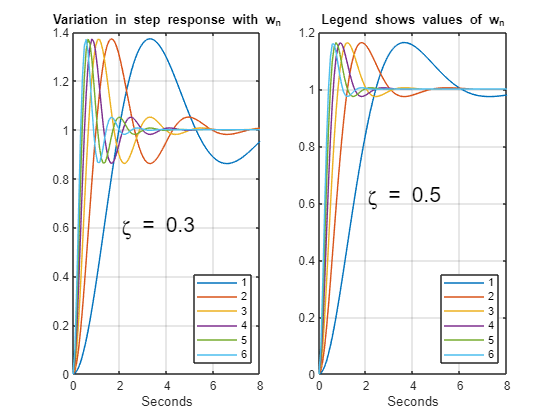

damping1 =[0.3];
wn1=[1:6];
t = linspace(0,8/wn1(1),100);
figure;clf;
subplot(121)
for k=1:6 
    G1{k}=tf(wn1(k)^2,[1,2*wn1(k)*damping1,wn1(k)^2]);
    [y1{k}]=step(G1{k},t);
    plot(t,y1{k});hold on
    leg1{k}=num2str(wn1(k));
end
grid
title(['Variation in step response with w_n'])
text(2/wn1(1),0.6,['\zeta = ',num2str(damping1)],'fontsize',16)
xlabel('Seconds')
legend(leg1,'Location',"southeast")

%%% Example 2 - faster natural frequency
wn=2;   
t = linspace(0,8/wn1(1),100);
damping1 =[0.5];
subplot(122)
for k=1:6
     G1{k}=tf(wn1(k)^2,[1,2*wn1(k)*damping1,wn1(k)^2]);
    [y1{k}]=step(G1{k},t);
    plot(t,y1{k});hold on
    leg1{k}=num2str(wn1(k));
end
grid
title(['Legend shows values of w_n'])
text(2/wn1(1),0.62,['\zeta = ',num2str(damping1)],'fontsize',16)
legend(leg1,'Location',"southeast")
xlabel('Seconds')
